## BOW Physiognomy

Sam Coleman and Caitlin Kantor

clear vars
clear
clf
clc
% MAYBE TRY non negative matrix factorization
% Create matrices for each institution
%commented out because we loaded it into a mat file

% for k = 1:75
%     pngFilename = sprintf('Br%d.png', k);    
%     fullFileName = fullfile('C:\Users\scoleman\MATLAB Drive\Everything', pngFilename);
%     if exist(fullFileName, 'file')
%         B = double(rgb2gray(imread(fullFileName)))/255.0;
%         %B = double(imread(fullFileName));
%         %B = rgb2gray(B);
%         B = reshape(B, [], 1);
%     end
%     Ball(:, k) = B;
% end
% 
% for k = 1:75
%     pngFilename = sprintf('Or%d.png', k);
%     fullFileName = fullfile('C:\Users\scoleman\MATLAB Drive\Everything', pngFilename);
%     if exist(fullFileName, 'file')
%         O = double(rgb2gray(imread(fullFileName)))/255.0;
%         O = reshape(O, [], 1);
%     end
%     Oall(:, k) = O;
% end
% 
% for k = 1:75
%     pngFilename = sprintf('Wr%d.png', k);
%     fullFileName = fullfile('C:\Users\scoleman\MATLAB Drive\Everything', pngFilename);
%     if exist(fullFileName, 'file')
%         W = double(rgb2gray(imread(fullFileName)))/255.0;
%         W = reshape(W, [], 1);
%     end
%     Wall(:, k) = W;
% end
% 
% save('TrainingData.mat', 'Ball', 'Oall', 'Wall')

%load B, O, W training data matrices
load TrainingData.mat

% figure()
% subplot(3, 3, 1)
% imagesc(reshape(Ball(:, 1), [100 100]))
% colormap('gray')
% subplot(3, 3, 2)
% imagesc(reshape(Ball(:, 22), [100 100]))
% colormap('gray')
% subplot(3, 3, 3)
% imagesc(reshape(Ball(:, 54), [100 100]))
% colormap('gray')
% subplot(3, 3, 4)
% imagesc(reshape(Oall(:, 15), [100 100]))
% colormap('gray')
% subplot(3, 3, 5)
% imagesc(reshape(Oall(:, 50), [100 100]))
% colormap('gray')
% subplot(3, 3, 6)
% imagesc(reshape(Oall(:, 68), [100 100]))
% colormap('gray')
% subplot(3, 3, 7)
% imagesc(reshape(Wall(:, 5), [100 100]))
% colormap('gray')
% subplot(3, 3, 8)
% imagesc(reshape(Wall(:, 26), [100 100]))
% colormap('gray')
% subplot(3, 3, 9)
% imagesc(reshape(Wall(:, 55), [100 100]))
% colormap('gray')

%Turn matrices into column vectors
%BCol = reshape(B, [100*100, 75])';
BCol = Ball';
OCol = Oall';
% OCol = reshape(O, [100*100, 75])';
% WCol = reshape(W, [100*100, 75])';

%Make mean centered
BCol = BCol - mean(BCol);
OCol = OCol - mean(OCol);

AllCol = cat(1, BCol, OCol);

%Find covariance matrices
Ba = (1/sqrt(9999)) * BCol;
Br = Ba' * Ba;
Oa = (1/sqrt(9999)) * OCol;
Or = Oa' * Oa;


Aa = (1/sqrt(9999)) * AllCol;
Ar = Aa' * Aa;

%Find eigenvectors (and values)
% [BV, BD] = eigs(Br, 40);
% Bbodies = BV;
% [OV, OD] = eigs(Or, 40);
% Obodies = OV;
% [WV, WD] = eigs(Wr, 40);
% Wbodies = WV;

[AV, AD] = eigs(Ar, 40)

AV =     0.0242    0.0200    0.0459   -0.0426    0.0269   -0.0317    0.0164    0.1245   -0.0040    0.0390   -0.0098    0.0573   -0.0169   -0.0273    0.0296    0.0059   -0.0154    0.0652   -0.0001   -0.0209   -0.0685    0.0750    0.0225    0.2432   -0.0434    0.0309   -0.0514    0.1107    0.0828    0.0280   -0.1198    0.1072   -0.0491   -0.0828   -0.0854    0.1326   -0.1328    0.1836    0.1083   -0.1397
    0.0164    0.0142    0.0281   -0.0259    0.0164   -0.0213    0.0095    0.0823   -0.0038    0.0246   -0.0067    0.0353   -0.0071   -0.0177    0.0190   -0.0008   -0.0042    0.0345    0.0008   -0.0144   -0.0422    0.0465    0.0140    0.1551   -0.0284    0.0209   -0.0343    0.0722    0.0496    0.0242   -0.0749    0.0660   -0.0303   -0.0573   -0.0482    0.0794   -0.0726    0.1136    0.0537   -0.0840
    0.0215    0.0149    0.0353   -0.0345    0.0221   -0.0311    0.0196    0.0869    0.0029    0.0230    0.0012    0.0422   -0.0014   -0.0245    0.0264   -0.0097    0.0025    0.0370    0.0034   

AD =     1.5700         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.1185         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8639         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

AllBodies = AV;

%See the eigenbodies
% for i = 1:40
%     figure()
%     hold on
%     imagesc(reshape(AllBodies(:, i), [100, 100]))
%     colormap('gray')
%     axis ij
%     hold off
% end

% subplot(2, 2, 1)
% imagesc(reshape(AllBodies(:, 1), [100, 100]))
% colormap('gray')
% axis ij
% subplot(2, 2, 2)
% imagesc(reshape(AllBodies(:, 10), [100, 100]))
% colormap('gray')
% subplot(2, 2, 3)
% imagesc(reshape(AllBodies(:, 20), [100, 100]))
% colormap('gray')
% axis ij
% subplot(2, 2, 4)
% imagesc(reshape(AllBodies(:, 30), [100, 100]))
% colormap('gray')
% axis ij

%Create into body space
% b_train = BCol * Bbodies;
% o_train = OCol * Obodies;
% 
% w_train = WCol * Wbodies;

all_train = AllCol * AllBodies;

%Prepare Test Data
counter = 0

counter = 0

for k = 76:100
    counter = counter + 1;
    pngFilename = sprintf('Br%d.png', k);    
    fullFileName = fullfile('C:\Users\scoleman\MATLAB Drive\Everything', pngFilename);
    if exist(fullFileName, 'file')
        BO_test = double(rgb2gray(imread(fullFileName)))/255.0;
        %B = double(imread(fullFileName));
        %B = rgb2gray(B);
        BO_test = reshape(BO_test, [], 1);
    end
    BO_test_all(:, counter) = BO_test;
end

counter = 25

counter = 25

for k = 76:100
    counter = counter + 1;
    pngFilename = sprintf('Or%d.png', k);    
    fullFileName = fullfile('C:\Users\scoleman\MATLAB Drive\Everything', pngFilename);
    if exist(fullFileName, 'file')
        BO_test = double(rgb2gray(imread(fullFileName)))/255.0;
        %B = double(imread(fullFileName));
        %B = rgb2gray(B);
        BO_test = reshape(BO_test, [], 1);
    end
    BO_test_all(:, counter) = BO_test;
end

%Babson is 0, Olin is 1
answerMatrix = ones([50 1]);
counter = 0;
for k = 1:25
    counter = counter + 1;
    answerMatrix(counter, 1) = 0;
end

save('Bo_test_data.mat', 'BO_test_all', 'answerMatrix')

%Load test data
load Bo_test_data.mat

%Prepare test data for anaylsis
BO_test_all = BO_test_all - mean(BO_test_all);
%BOW_test_all = BOW_test_all';
bo_test = BO_test_all' * AllBodies;

results = knnsearch(all_train, bo_test);
for i = 1:50
    results(i) = idivide(int16(results(i)), int16(50));
end

for i = 1:50
    if results(i) == 3
        results(i) = 2;
     end
end
results;

accuracy = mean(answerMatrix == results)

accuracy = 0.3400

## Determine Accuracy of Method 1

accuracies1 = ones(150, 1);
[AV1, AD1] = eigs(Ar, 150);

for num_components = 1:150
    num_components;
    AllBodies1 = AV1(:, 1:num_components);
    all_train1 = AllCol * AllBodies1;
    BO_test_all1 = BO_test_all - mean(BO_test_all);
    bo_test1 = BO_test_all1' * AllBodies1;
    
    results1 = knnsearch(all_train1, bo_test1);
    for i = 1:50
        results1(i) = idivide(int16(results1(i)), int16(50));
    end

    for i = 1:50
        if results1(i) == 3
            results1(i) = 2;
        end
    end
    
    accuracies1(num_components) = mean(answerMatrix == results1);
end

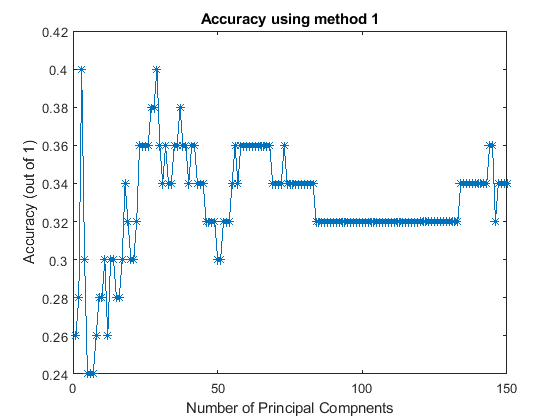

%Plot Accuracy
plot(accuracies1, ...
    '*-')
title('Accuracy using method 1')
xlabel('Number of Principal Compnents')
ylabel('Accuracy (out of 1)')

% %Create plot for #principal components vs accuracy
% accuracies1 = ones(75, 1);
% for i = 1:225
%     i
%     [AV1, AD1] = eigs(Ar, i);
%     AllBodies1 = AV1;
%     all_train1 = AllCol * AllBodies1;
%     BOW_test_all1 = BOW_test_all - mean(BOW_test_all);
%     bow_test1 = BOW_test_all1' * AllBodies1;
%     
%     results = knnsearch(all_train, bow_test);
%     for k = 1:75
%         results(k) = idivide(int16(results(k)), int16(75));
%     end
% 
%     for k = 1:75
%         if results(k) == 3
%             results(k) = 2;
%         end
%     end
%     accuracies1(i) = mean(answerMatrix == results);
% end

%%Create a box around faces
% scaleFactor = 25;
% locationFactor = -.5*scaleFactor;
% test = reshape(Ball(:, 20), [100 100]);
% size(test);
% faceDetector = vision.CascadeObjectDetector;
% Testbox = step(faceDetector, test) %+ [locationFactor locationFactor scaleFactor scaleFactor];
% imagesc(test)
% colormap('gray')
% vision.ShapeInserter('BorderColor', 'Custom', 'CustomBorderColor',[255 255 0]);
% TestFaces = step(vision.ShapeInserter, test, int32(Testbox)); 
% figure, imagesc(TestFaces), title('Detected faces');
% colormap('gray')
% axis 'square'

% testCrop = imcrop(test, Testbox);
% imshow(testCrop)